clc
clear all
close all

# Motor de corriente continua (MCC)

Modelo


$$v_a = R_a i_a + L_a \frac{di_a}{t} + v_{rot} \\
J \frac{d\omega}{dt} = T_e - T_m \\
v_{rot} = K\omega \\
T_e = K i_a$$


## Parámetros de la MCC

[Parametros MCC](https://www.ijstr.org/final-print/feb2020/Parameter-Identification-Of-A-Dc-Motor.pdf)

MCC = struct()

MCC = struct with no fields.


Eléctricos

MCC.Ra = 0.5; %[Ohm]
MCC.La = 1.5e-3; %[H]
MCC.K = 0.05; %[V/rpm]

Mecánicos

MCC.J = 2.5e-4; %[kg*m^2]
MCC.D = 1e-4; %[N*m*s/rad]
MCC.w0 = 0; %[rpm]

MCC

MCC = struct with fields:
    Ra: 0.5000
    La: 0.0015
     K: 0.0500
     J: 2.5000e-04
     D: 1.0000e-04
    w0: 0


# Control

Velocidad

P = 0.1;
I = 1;

T_step = 0; %[s]
w_step = 50; %[rpm]

# Simulación

Tf = 5; %[s]
Ts = 1e-4; %[s]
% open("SimulacionMCC.slx")
out = sim("SimulacionMCC.slx")

out =   Simulink.SimulationOutput:

                     ia: [1x1 timeseries] 
                   tout: [50001x1 double] 
                     va: [1x1 timeseries] 
                      w: [1x1 timeseries] 
                  w_ref: [1x1 timeseries] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


t = out.tout;
w = out.w.data;
w_ref = out.w_ref.data;
ia = out.ia.data;
va = out.va.data;

# Graficas

figure

Velocidad

subplot(2, 1, 1)
plot(t, w)
hold on
plot(t, w_ref)
hold off
xlabel("t [s]")
ylabel("w [rpm]"); ylim([-1, w_step*1.1])
title("Control de velocidad")
legend("w", "w*")

Tensión y corriente

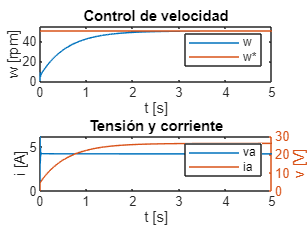

subplot(2, 1, 2)
plot(t, ia)
ylabel("i [A]")
yyaxis right
plot(t, va)
ylabel("v [V]")
xlabel("t [s]")
title("Tensión y corriente")
legend("va", "ia")